## INTRODUCTION

A travers ce script, nous allons étudier les résultats du BFGS avec les deux premières fonction de test données en énoncé. Puis, nous étudierons les deux fonctions supplémentaires pour trouver la valeur de x* pour divers valeurs de n.

Nous avons pu voir lors du TP1 de MATLAB que la méthode de Nexton-Raphson diverge violemment si le point de départ choisi n'est pas proche de l'origine, puis, il faut calculer le Hessien ou le Jacobien associé, ce qui n'est pas toujours évident. Ensuite, il reste la résolution des n systèmes linéaires.

L'idée général avec le BFGS est de calculer une approximation de l'inverse du Hessien par une matrice H, symétrique et définie positive. C'est une méthode itérative, c'est-à-dire qu'à chaque ittération, le méthode va converger vers une approximation corecte de l'inverse du Hessien.

L'algorithme général du BFGS peut se présenter sous cette forme :

**INITIALISATION :** $x_0$ le point de départ, $\varepsilon >0$ la précision des calculs.

        On calcule $g_0 =\nabla f\left(x_0 \right)$ et on initialise le Hessien approché : $H_0 ={Id}_n$

        
$$k\longleftarrow 0$$


**TANT QUE :** $\|g_k \|<\epsilon$ faire :

        On calcule $d_k =-H_k g_k$

        On effectue la recherche linéaire* en partant de $t=1$pour obtenir $x_{k+1} =x_k +t_k d_k$ et $g_{k+1} =\nabla f\left(x_{k+1} \right)$

        On calcule la nouvelle version de $H_{k+1}$ grâce à la formule (1) de l'énoncé

        
$$k\longleftarrow k+1$$


**FIN**

La recherche linéaire choisi ici est la recherche l'inéaire de Wolfe

**Initialisation des paramètres**

epsilon = 10 ^ -7;
iter_max = 500;
rlin = @wolfe;
[X,Y] = meshgrid(0:0.1:5,0:0.1:10);

## PREMIÈRE FONCTION DE TEST

Cette première fonction est définie de la manière suivante :


$$f\left(x,y\right)=100\;\left(y-\mathrm{x²}\right)²+\left(1-x\right)²$$


On prend ici comme vecteur initial $x_0 ={\left(0,0\right)}^{\prime }$

x0 = [0, 0]';

**Test sur la 1ère fonction de test :**

[ft1, gt1] = Fct_test_1(x0);

La valeur de f(x0) est :

disp(ft1);

     1



La valeur de g(x0) est :

disp(gt1);

    -2
     0



% On lance BFGS_main :
[ite_x, ite_F, xk, fk, k] = BFGS_main(@Fct_test_1, rlin, x0, epsilon, iter_max);

Itération numéro     1 -> F =  1.00025167e+00 avec x = 0.2592163086, 0.0000000000 
Itération numéro     2 -> F =  9.22199768e-01 avec x = 0.3569692938, 0.0561030780 
Itération numéro     3 -> F =  4.15679319e-01 avec x = 0.3695225692, 0.1500293356 
Itération numéro     4 -> F =  3.85999889e-01 avec x = 0.3822326327, 0.1394962056 
Itération numéro     5 -> F =  2.97397257e-01 avec x = 0.4848520836, 0.2171874430 
Itération numéro     6 -> F =  2.78031979e-01 avec x = 0.4753204397, 0.2311672086 
Itération numéro     7 -> F =  1.66607207e-01 avec x = 0.6127413982, 0.3625531908 
Itération numéro     8 -> F =  1.45243097e-01 avec x = 0.6788821737, 0.4403562795 
Itération numéro     9 -> F =  7.65758244e-02 avec x = 0.7257820010, 0.5230442561 
Itération numéro    10 -> F =  5.27097491e-02 avec x = 0.8155017976, 0.6513793016 
Itération numéro    11 -> F =  3.11152770e-02 avec x = 0.8277601944, 0.6813807256 
Itération numéro    12 -> F =  1.42330295e-02 avec x = 0.9004674789, 0.8042642139 
Itér

La valeur de x* à l'itération k est :

disp(xk)

    1.0000
    1.0000



Le nombre d'iteraion k est :

disp(k)

    21



La valeur de f à l'itération k est :

disp(fk)

   6.2610e-21



 On trace la fonction et on affiche les itérations successives.

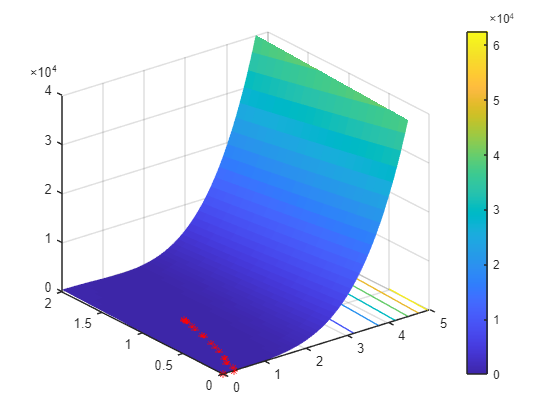

Z = 100*((Y - X.^2).^2) + (1 - X).^2;
surfc(X,Y,Z, 'EdgeColor', 'none')
hold on
scatter3(ite_x(:,1), ite_x(:,2), ite_F, '*', 'MarkerEdgeColor', 'r');
hold off

xlim([0.00 5.00])
ylim([0.00 2.00])
zlim([0 40000])
view([-38 28])
colorbar

On constate bien sur le graphique que la solution trouvé précédément correspond : $x^* ={\left(1,1\right)}^{\prime }$

## DEUXIÈME FONCTION DE TEST

Cette fonction est donnée dans l'énnoncé de cette manière :


$$f\left(x,y\right)=\left(x+y\right)²+{\left(2\left(\mathrm{x²}+\mathrm{y²}-1\right)-\frac{1}{3}\right)}^2$$


On prend ici comme vecteur initial $x_0 ={\left(\sqrt{\frac{7}{6}},0\right)}^{\prime }$

x0 = [sqrt(7 / 6), 0]';

**Test sur la 2ème fonction de test  :**

[ft2, gt2] = Fct_test_2(x0);

La valeur de f(x0) est :

disp(ft2);

    1.1667



La valeur de g(x0) est 

disp(gt2);

    2.1602
    2.1602



% On lance BFGS_main :
[ite_x, ite_F, xk, fk, k] = BFGS_main(@Fct_test_2, rlin, x0, epsilon, iter_max);

Itération numéro     1 -> F =  1.05729167e+00 avec x = 0.8100925873, -0.2700308624 
Itération numéro     2 -> F =  6.50191228e-01 avec x = 1.0970003786, -0.4556770804 
Itération numéro     3 -> F =  4.49896463e-01 avec x = 0.9489418825, -0.7674912844 
Itération numéro     4 -> F =  2.81128149e-01 avec x = 0.7096182308, -0.6330706100 
Itération numéro     5 -> F =  1.19660763e-02 avec x = 0.7639994814, -0.7288222597 
Itération numéro     6 -> F =  8.58890131e-04 avec x = 0.7705961850, -0.7663874403 
Itération numéro     7 -> F =  3.58438725e-05 avec x = 0.7667688236, -0.7607829926 
Itération numéro     8 -> F =  8.37045467e-06 avec x = 0.7652339684, -0.7623461553 
Itération numéro     9 -> F =  4.05631620e-10 avec x = 0.7637666260, -0.7637651811 
Itération numéro    10 -> F =  5.66807269e-14 avec x = 0.7637626770, -0.7637626311 
Itération numéro    11 -> F =  2.93846420e-24 avec x = 0.7637626158, -0.7637626158 


La valeur de x* à l'itération k est :

disp(xk)

    0.7638
   -0.7638



Le nombreb d'iteraion k est :

disp(k)

    11



La valeur de f à l'itération k est : 

disp(fk)

   2.9385e-24



On trace la fonction et on affiche les itérations successives.

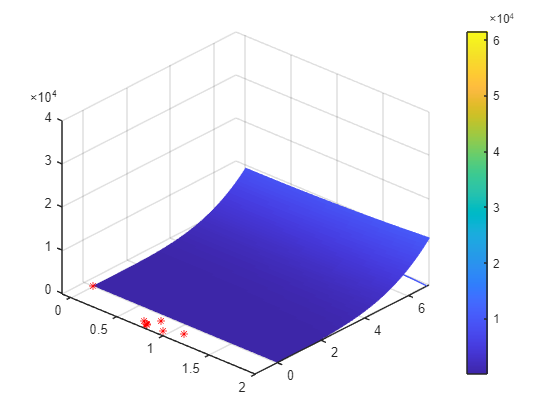

Z = (X + Y).^2 + (2 * (X.^2 + Y.^2 - 1) - 1/3).^2;
surfc(X,Y,Z, 'EdgeColor', 'none')
hold on
scatter3(ite_x(:,1), ite_x(:,2), ite_F, '*', 'MarkerEdgeColor', 'r');

xlim([-0.10 2.00])
ylim([-1.00 7.00])
zlim([0 40000])
view([42 35])
colorbar

On constate bien sur le graphique que la solution trouvé précédément correspond : $x^* ={\left(\sqrt{\frac{7}{12}},-\sqrt{\frac{7}{12}}\right)}^{\prime }$

## PREMIÈRE FONCTION DONT ON NE CONNAIS PAS x*

Dans cette fonction et la suivante, seule la fonction et le vecteur de départ sont données.

Soit la fonction $f_1 \left(x\right)=\sum_{i\;=\;2\;}^n i\;{\left(2x_i -x_{i-1} \right)}^2$

Avec le vecteur initial $x_0 ={\left(1,1,1,1,1\right)}^{\prime }$

x0 = [1, 1, 1, 1, 1, 1]';

**Test sur la première fonction dont on ne connais pas x***

[f1, g1] = Fct_1(x0);

La valeur de f(x0) est :

disp(f1);

    20



La valeur de g(x0) est :

disp(g1);

    -4
     2
     4
     6
     8
    24



% On lance BFGS_main:
[~, ~, xk, fk, k] = BFGS_main(@Fct_1, rlin, x0, epsilon, iter_max);

Itération numéro     1 -> F =  1.68750000e+01 avec x = 1.2500000000, 0.8750000000 
Itération numéro     2 -> F =  1.09803614e+01 avec x = 1.4116287103, 0.8067894968 
Itération numéro     3 -> F =  3.14405140e+00 avec x = 1.4368724957, 0.8162152400 
Itération numéro     4 -> F =  3.02731670e-01 avec x = 1.4490948697, 0.8058730605 
Itération numéro     5 -> F =  1.38714205e-01 avec x = 1.4710630761, 0.7670963792 
Itération numéro     6 -> F =  6.98782140e-02 avec x = 1.4789542864, 0.7324341423 
Itération numéro     7 -> F =  5.86991486e-02 avec x = 1.4771935362, 0.7466684447 
Itération numéro     8 -> F =  3.41447287e-03 avec x = 1.4782024958, 0.7393702777 
Itération numéro     9 -> F =  2.64573849e-03 avec x = 1.4785577320, 0.7355838217 
Itération numéro    10 -> F =  1.28201116e-03 avec x = 1.4776339710, 0.7393671404 
Itération numéro    11 -> F =  7.95484187e-04 avec x = 1.4777715097, 0.7369111161 
Itération numéro    12 -> F =  4.61148643e-05 avec x = 1.4775246799, 0.7379017642 
Itér

La valeur de x* à l'itération k est :

disp(xk)

    1.4769
    0.7385
    0.3692
    0.1846
    0.0923
    0.0462



Le nombre d'iteraion k est :

disp(k)

    25



La valeur de f à l'itération k est :

disp(fk)

   1.5646e-20



On ne peux pas tracer la fonction ici car la taille du vercteur initiale est supérieur à 2.

## DEUXIÈME FONCTION DONT ON NE CONNAIS PAS x*

Soit la fonction $f_2 \left(x\right)={10}^{-5} \;\times \sum_{i=1}^n {\left(x_i -1\right)}^2 +{\left(\sum_{i=1}^n x_i^2 -0\ldotp 25\right)}^2$

Avec le vecteur initial $x_0 ={\left(1,2,3,4,5,6\right)}^{\prime }$

x0 = [1, 2, 3, 4, 5, 6]';

**Test sur la deuxième fonction donnée  :**

[f2, g2] = Fct_2(x0);

La valeur de f(x0) est :

disp(f2);

   8.0103e+03



La valeur de g(x0) est :

disp(g2);

   1.0e+03 *

    0.3580
    0.7160
    1.0740
    1.4320
    1.7900
    2.1480



% On lance BFGS_main:
[~, ~, xk, fk, k] = BFGS_main(@Fct_2, rlin, x0, epsilon, iter_max);

Itération numéro     1 -> F =  1.67611626e+02 avec x = -0.3984375000, -0.7968750781 
Itération numéro     2 -> F =  6.31828686e+01 avec x = -0.3222178295, -0.6444519076 
Itération numéro     3 -> F =  1.64432833e+01 avec x = -0.2478169543, -0.4946639518 
Itération numéro     4 -> F =  4.39572188e+00 avec x = -0.1798692719, -0.3843271606 
Itération numéro     5 -> F =  1.13766731e+00 avec x = -0.4109576066, -0.5008737561 
Itération numéro     6 -> F =  2.41548839e-01 avec x = 0.2215502985, -0.0246211158 
Itération numéro     7 -> F =  2.60819435e-03 avec x = 0.0548447163, -0.1276676769 
Itération numéro     8 -> F =  4.13234972e-04 avec x = 0.0479027533, -0.1310012503 
Itération numéro     9 -> F =  1.23119330e-04 avec x = 0.0445705902, -0.1325521216 
Itération numéro    10 -> F =  1.22783289e-04 avec x = 0.0444624541, -0.1326002168 
Itération numéro    11 -> F =  1.22782988e-04 avec x = 0.0444672584, -0.1325962894 
Itération numéro    12 -> F =  1.22781781e-04 avec x = 0.0445010796, -0

La valeur de x* à l'itération k est :

disp(xk)

    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000



Le nombre d'iteraion k est :

disp(k)

   387



La valeur de f à l'itération k est :

disp(fk)

   1.5000e-05



## CONLCUSION

Nous avons pu étudier lors de ce TP, un algorithme nous premettant de résoudre un problème d'optimisation non linéaire sans contraintes.

Nous avons pu tester cet algorithme sur quatre fonctions différentes, et la méthode converge assez bien et surtout rapidement. Cependant, elle necessite beaucoup plus d'itérations lorsque n devient grand.